clear all

# Oppgave 1				

Platene til en parallell-plate-kondensator ligger 

d = 2.50 * 10^-3; % m

fra hverandre og ladningen på hver av platene har størrelsen 

Q = 80.0 * 10^-9; % C

Platene ligger i vakum. Det elektriske feltet mellom platene er 

E = 4.00 * 10^6 ; % V/m

### (a) Hvor stor er potensialforskjellen mellom platene. 

Ved å bruke formelen for det elektriske feltet mellom platene $E=\frac{Q}{\epsilon_0 A}=\frac{U_{\mathrm{ab}} }{d}$ får vi at potensialforskjellen er:

U_ab = E*d % V

U_ab =        10000


### (b) Hvor stort areal har hver av platene. 

Med samme formel som i (a) har vi likningen $E=\frac{Q}{\epsilon_0 A}\;\;\;\;\Rightarrow \;\;\;\mathrm{EA}=\frac{Q}{\epsilon_0 }\;\;\;\;\Rightarrow \;\;\;\;A=\frac{Q}{\epsilon_0 E}$

e_0 = 8.854187 * 10^-12; % F
A = Q/(e_0 * E) % m^2

A =    0.002258818342102


### (c) Hvor stor er kapasistansen. 

Kapasistansen for en platekondensator er gitt ved: $C=\epsilon_0 \frac{A}{d}$ altså:

C = e_0 * A/d % F/m

C =      8.000000000000000e-12


Vi kan også finne den ved formelen: $C=\frac{Q}{U_{\mathrm{ab}} }$

C = Q/U_ab

C =      8.000000000000000e-12


# Oppgave 4 - Kapasitans til et oskiloskop. 

Oskiloskoper har parallelle metallplater på innsiden for å bøye elektronstråen. Typisk er disse kvadratiske plater med sider 

s = 3.0 * 10^-2; % m
A = s*s

A =      9.000000000000000e-04


med innbyrdes avstand 

d = 5.0 * 10^-3; % m

med vakuum mellom. 

## Hvor stor er kapasistansen til disse platene? 

Kapasitansen mellom platene er gitt ved $C=e_0 \frac{A}{d}$

C = e_0 * A/d

C =      1.593753660000000e-12


# Oppgave 15 Elektrisk ål. 

Elektrisk ål genererer store potensialforskjeller som brukes til å lamme fiender og byttedyr. Disse potensialforskjellene er produsert av celler som hver kan generere 

Spenning_per_Celle = 0.10; % V

Vi kan fint modellere slike celler som kondensatorer. 

## (a) Hvordan bør slike celler kobles (i serie eller parallell) for å lage en spenning som er større enn 0,10 V?. 

Vi ønsker altså å øke den totale spenningen og vi vet at dersom vi kobler komponenter i parallell vil den totale spenninge  være den samme som spenningen over hver komponent, da kan altså ikke cellene kobles i paralell ettersom at vi da alltid vil ha en spenning på 0.10 V. Vi må altså koble cellene i serie, hvor den totale poteniskaforskjellen er lik summen av alle komponentene i serien.

## (b) Hvor mange celler må kobles sammen for å produsere 500 V ved å bruke koblingen (a)? 

Som forklart i (a) kobler vi i serie, og for å få en total spenning på 

Spenning_totalt = 500; % V

trenger vi altså

celler = Spenning_totalt/Spenning_per_Celle

celler =         5000


for å få en total potensialforkzjell/spenning på 500V

# Oppgave 17	

# 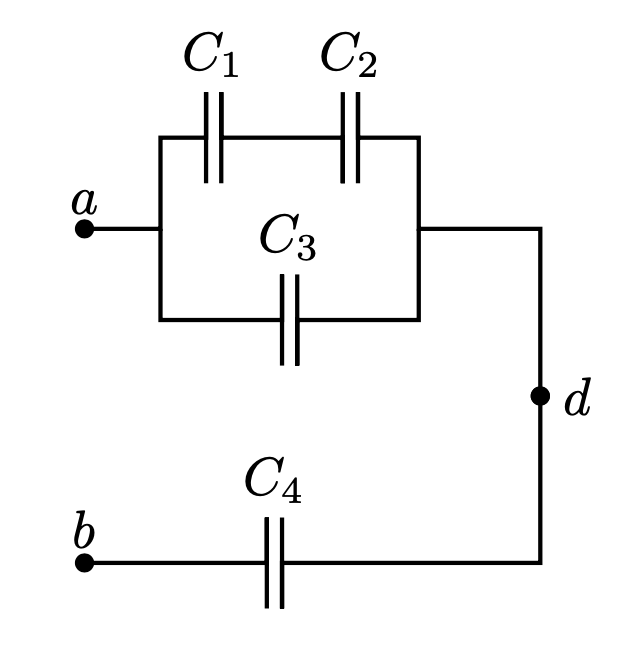				

I figuren har hver kondensator kapasistans 

C_n = 4.00 * 10^-6; % F

og potensialforskjellen/spenning mellom punktene a og b er: 

U_ab = 28.0; % V 

Regn ut: 

## (a) ladningen på hver kondensator

Først forenkler vi kretsen og finner kapasitansen for de forskjellige kompnentene, og deretter for hele kretsen:


$$C_1 \;\mathrm{og}\;C_2 \;\mathrm{er}\;i\;\mathrm{serie}:C_{12} =\frac{\left(C_1 *C_2 \right)}{C_1 +C_2 }$$


C_12 = (C_n*C_n)/(C_n+C_n);


$$C_{12} \;\mathrm{og}\;C_3 \;i\;\mathrm{parallell}:C_{123} =C_{12} +C_3$$


C_123 = C_12 + C_n;


$$C_{123} \;\mathrm{og}\;C_4 \;i\;\mathrm{serie}:C_{\mathrm{eff}} =\frac{\left(C_{123} *C_4 \right)}{C_{123} +C_4 }$$


C_eff = (C_123*C_n)/(C_123+C_n);

Siden vi nå vet kapasitansen til hele kretsen, kan vi finne ladningen over hele kretsen, og siden $C_{123}$ og $C_4$er koblet i serie vil ladningen over disse komponentene være den samme som for hele kretsen. 

Altså: $Q_{123} =Q_4 =Q_{\mathrm{eff}}$


$$C=\frac{Q}{U}\;\;\;\;\Rightarrow \;\;\;Q_{\mathrm{eff}} =C_{\mathrm{eff}} *V_{\mathrm{ab}}$$


Da får vi:

Q_eff = C_eff * U_ab;
Q_4 = Q_eff;
Q_123 = Q_eff;

Videre vet vi at i en parallellkobling vil hver gren ha samme potenisalforskjell, mens ladningen vil være summen av ladningen av hver gren:


$$U_{123} =U_{12} =U_3 \;\;\;\;\;\;\;\Rightarrow \;\frac{Q_{123} }{C_{123} }=\frac{Q_{12} }{C_{12} }=\frac{Q_3 }{C_3 }$$
    


$$Q_{123} =Q_{12} +Q_3 \Rightarrow Q_3 =Q_{123} -Q_{12}$$
         
$$Q_{12} =Q_1 =Q_2$$


Dette gir oss at: $Q_{12} =\frac{Q_{123} *C_{12} }{C_{123} }$

Q_12 = Q_123*C_12/C_123;
Q_3 = Q_123 - Q_12;
fprintf('Vi får altså ladningene: \nC1 = %d C\nC2 = %d C\nC3 = %d C\nC4 = %d C', Q_12, Q_12,Q_3,Q_4)

Vi får altså ladningene: 
C1 = 2.240000e-05 C
C2 = 2.240000e-05 C
C3 = 4.480000e-05 C
C4 = 6.720000e-05 C

## (b) potensialforskjellen over hver kondensator 

fra oppgave (a) har vi at:


$$U_n =\frac{Q_n }{C_n }$$


dette gir:

U_1 = Q_12/C_n

U_1 =    5.600000000000000


U_2 = Q_12/C_n

U_2 =    5.600000000000000


U_3 = Q_3/C_n

U_3 =   11.200000000000001


U_4 = Q_4/C_n

U_4 =   16.800000000000004


## (c) potensialforskjellen mellom punktene a og d. 


$$U_{\mathrm{ad}} =U_{\mathrm{eff}} -U_4$$


U_ad = U_ab - U_4

U_ad =   11.199999999999996


# Oppgave 1 - Lynnedslag. 

Strømmen i et lynnedslag kan komme opp i hele 25000 ampere og varer i ca 40 μs. Hvor mye ladning transporter et slikt lyn fra skyene til bakken?  

I = 25000; % A
t = 40 *10^-6; % s


$$I=\frac{\Delta q}{\Delta t}\Rightarrow \Delta Q=I*t$$


Q = I*t

Q =    1.000000000000000


# Oppgave 3				

En strøm på 

I = 5; % Ampere = Coulumb/sekund

går igjennom en “12-gauge” kobbertråd med 

diameter = 2.05 * 10^-3; % meter

og igjennom en lyspære. Kobber har 

frie_elektroner = 8.5 * 10^28; % per meter

## (a) Hvor mange elektroner passerer lyspæren hvert sekund? 

Elektronladningen = 1.602 * 10^-19; % Coulomb
ant_eletrkoner = I/Elektronladningen

ant_eletrkoner =      3.121098626716604e+19


## (b) Hvor stor strømtetthet er det i kobbertråden? 

Strømtettheten er gitt ved strøm per areal:

A = pi*(diameter/2)^2

A =      3.300635781677776e-06


Stromtetthet = I/A % A/m^2

Stromtetthet =      1.514859660601027e+06


## (c) Hva er den typiske hastigheten ($v_d$) til hvert elektron i kobbertråden? 

Formelen for strømtetthet gir oss det vi trenger: 

$J={\mathrm{nqv}}_d \Rightarrow v_d =\frac{J}{n*q}$ hvor n er antall elektroner, J er strømtettheten og q er størrelsen per ladning 

v_d = Stromtetthet/(frie_elektroner*Elektronladningen)

v_d =      1.112476801498881e-04


## (d) Hvilke av svarene i (a,b,c) bli mindre, større eller uendret hvis du bytter en kobbertråden med en tråd som har dobbelt så stor diameter?

	(a) - uendret

	(b) - mindre

	(c) - mindre

# Oppgave 5					

Kobber har 

8,5·10 frie elektroner per m. Igjennom en 

l = 71.0 * 10^-2; % meter

lang “12-gauge” kobbertråd med diameter 

diameter = 2.05 *10^-3; % meter
A = pi*(diameter/2)^2;

går det en strøm 

I = 4.85; % A

## (a) Hvor lang tid bruker et elektron på å bevege seg fra den ene enden av tråden til den andre?

Finner først hastigheten til hvert elektron:

J = I/A;
v_d = J/(frie_elektroner*Elektronladningen);

deretter tiden det tar for et elektron å gå fra en ende av tråden til den andre med denne hastigheten:

t = l/v_d % sekunder

t =      6.579541810673290e+03


## (b) Svar på det samme som i (a) for en “6-gauge” kobbertråd, (diameter 4,12mm) med samme strøm som i (a).

 Finner først hastigheten til hvert elektron:

diameter = 4.12*10^-3;
A = pi*(diameter/2)^2;
J = I/A;
v_d = J/(frie_elektroner*Elektronladningen);

deretter tiden det tar for et elektron å gå fra en ende av tråden til den andre med denne hastigheten:

t = l/v_d % sekunder

t =      2.657555610020053e+04


## (c) Generelt sett, hvordan påvirker varierende diameter til en kobber-tråd drifthastigheten $v_d$, når strømmen holdes konstant.

 vi observerer at med en mindre diameter, men med samme strøm, synker hastigheten til elektronene.

# Oppgave 13

En “14 gauge” (amerikansk standard) kobberledning med 

diameter = 1.628 *10^-3; % meter 

bærer en strøm på 

I = 12.5 * 10^-3; % Ampere 
A = pi*(diameter/2)^2 % m^2

A =      2.081606725897982e-06


## (a) Hvor stor er potensialforskjellen over 2,00 m av denne tråden? 

p_kobber = 1.72 * 10^-8; % Ohm meter
l = 2; % meter

først finner vi det elektriske feltet


$$E=p*J=p*\left(\frac{I}{A}\right)$$


E = p_kobber * (I/A)

E =      1.032856001689038e-04


Da kan vi finne potensialforskjellen:


$$U=E*l$$


U = E * l

U =      2.065712003378077e-04


Vi finner først den samelde motstanden i tråden:


$$R=p\frac{l}{A}$$


R=p_kobber*l/A

R =    0.016525696027025


siden vi har strømmen kan vi bruke Ohms lov til å finne potensialforskjellen:

U = R*I

U =      2.065712003378077e-04


## (b) Hva ville svaret i (a) vært hvis tråden var laget av sølv istedet for kobber? 

Sølv har en annen motstand per meter på:

p_solv = 1.47 * 10^-8; % ohm meter
U = (p_solv*l/A)*I

U =      1.765463165677775e-04


# Oppgave 23				

En strømførende gull-ledning har 

diameter = 0.84 * 10^-3; % meter
r = diameter / 2;
A = pi*r^2

A =      5.541769440932395e-07


Det elektriske feltet i ledningen er er 

E = 0.49; % V/M

## Hva er: 

## (a) strømmen i lederen

p_gull = 2.44 * 10^-8; % Ohm meter

formelen for resisitivitet gir oss: $p=\frac{E}{J}=\frac{E}{\left(I/A\right)}=\frac{\mathrm{EA}}{I}\Rightarrow I=\frac{E*A}{p}$

I = E * A / p_gull 

I =   11.128963221544563


## (b) potensialforskjellen mellom to punkter på ledningen med avstand 6,4 m 

l = 6.4; % meter

Over 6,4 meter vår vi potensialforskjellen:

U = E * l

U =    3.136000000000000


## (c) motstanden til 6,4 m av denne ledningen

bruker Ohms lov:

R = U / I

R =    0.281787255252045
